Declaração

filenameA = "vga_in_1.bmp";
filenameB = "vga_in_2.bmp";
filenameOut = "vga_out_1.bmp";

inputA = imread(filenameA)

inputA = 480×640×3 uint8 array
inputA(:,:,1) =

   182   206   229   241   248   247   243   239   238   229   217   209   210   210   210   209   212   199   169   127   109   111   112   104   101   107   109   103    98    95    94    91    86    80    74    72    73    77    87    94    80    74    77    80    73    74    80    86    81    90   100   101    92    90    93    94    93    98   101    95    93    95    98    99    97    93    91    91    93    96    94    88    86    85    83    81    80    81    81    81    81    83    82    72    70    70    70    67    59    53    57    68    69    61    54    61    71    71    64    61    64    65    65    68    72    74   105   165   217   239   245   253   255   251   225   135    61    35    48    48    38    32    33    26    26    46    80   124   187   198   162   115   117   123   111    98    98   138   176   175   149   123   125   145   155   149   139   153   162   158   147   145   159   171   171   157   153   167   1

inputB = imread(filenameB)

inputB = 480×640×3 uint8 array
inputB(:,:,1) =

   182   206   229   241   248   247   243   239   238   229   217   209   210   210   210   209   212   199   169   127   109   111   112   104   101   107   109   103    98    95    94    91    86    80    74    72    73    77    87    94    80    74    77    80    73    74    80    86    81    90   100   101    92    90    93    94    93    98   101    95    93    95    98    99    97    93    91    91    93    96    94    88    86    85    83    81    80    81    81    81    81    83    82    72    70    70    70    67    59    53    57    68    69    61    54    61    71    71    64    61    64    65    65    68    72    74   105   165   217   239   245   253   255   251   225   135    61    35    48    48    38    32    33    26    26    46    80   124   187   198   162   115   117   123   111    98    98   138   176   175   149   123   125   145   155   149   139   153   162   158   147   145   159   171   171   157   153   167   1

output = uint8(zeros(480,680,3))

output = 480×680×3 uint8 array
output(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

output2 = uint8(zeros(480,680,3))

output2 = 480×680×3 uint8 array
output2(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Loop

tic
for i=1:size(inputA,1)
    for j=1:size(inputA,2)
        for k=1:3
            if inputA(i,j,k) == inputB(i,j,k)
                output(i,j,k) = uint8(128);
                output2(i,j,k) = uint8(128);
            else
                output(i,j,k) = uint8(inputA(i,j,k));
                output2(i,j,k) = uint8(inputB(i,j,k));
            end
        end
    end
end
toc

Elapsed time is 3.893248 seconds.


Finalização

output

output = 480×680×3 uint8 array
output(:,:,1) =

   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   1

imwrite(output, filenameOut);


Comparação

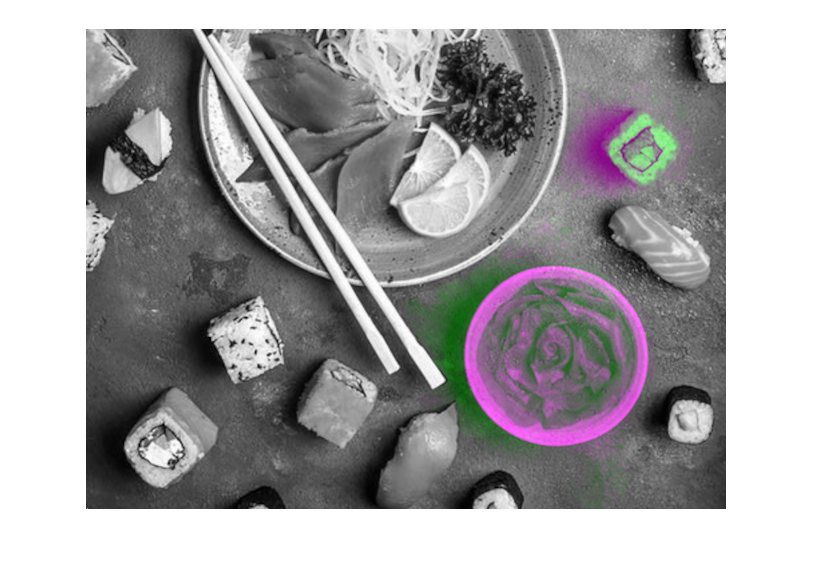

obj = imshowpair(inputA,inputB);

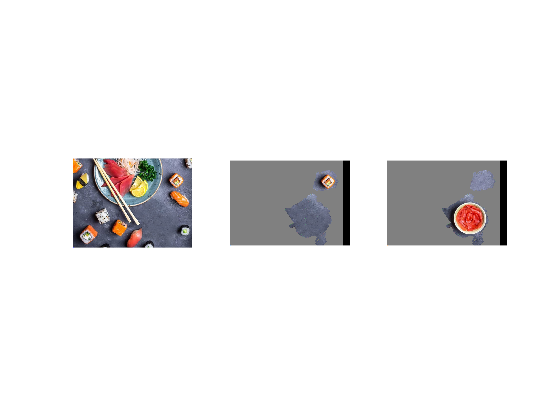

figure 
subplot(1,3,1)
imshow(inputA)
subplot(1,3,2)
imshow(output)
subplot(1,3,3)
imshow(output2)